
$$O(2): \ O^T O=I \ \wedge \ det(O)=\pm1$$


syms t
Rt=[cos(t) -sin(t);
    sin(t)  cos(t)];
Px=[-1 0;0 1];
Py=[1 0;0 -1];


$$SO(2): \ O^T O=I \ \wedge \ det(O)=1$$


Rt=[cos(t) -sin(t);
    sin(t)  cos(t)];


$$Baker-Campbell-Hausdorff \ formula:$$



$$e^X \cdot e^Y=e^{X+Y+\frac{1}{2}[X,Y]+\frac{1}{12}[X,[X,Y]]-\frac{1}{12}[Y,[X,Y]]+...}$$



$$QUATERNIONS:$$



$$The \ quaternion \ representation \ of \ the \ rotation \ may \ be \ expressed \ as \ q=cos(\theta /2)+sin(\theta /2)(u_bi+u_cj+u_dk), \ where \\ \theta  \ is \ the \ angle \ of \ rotation \ and \ [u_b, u_c, u_d] \ is \ the \ axis \ of \ rotation.$$



$$q=aI+bi+cj+dk$$



$$ijk=-1$$


%quaternion matrices
syms a b c d x y z real

I=eye(2);

i=[0 1;
  -1 0];

j=[0  1i;
   1i  0];

k=[1i  0;
    0 -1i];

% a quaternion
q=@(a,b,c,d) a*I+b*i+c*j+d*k;
% if det(q)=1 it is a unit quaternion
det(q(a,b,c,d))

$$ans = a^{2}+b^{2}+c^{2}+d^{2}$$

%a vector
v=@(x,y,z) x*i+y*j+z*k;
%if det(v)=1 it is a unit vector
det(v(x,y,z))

$$ans = x^{2}+y^{2}+z^{2}$$

%rotation axis
u=a*i+b*j+c*k;
%rotation matrix, observe that t=0:4*pi
R=@(t) cos(t/2)*I+sin(t/2)*u;

%Now we find which coordinate of S^3 results which transformation
%rotation axes lie on the surface of the sphere with the coordinates u=(0,x,y,z)
%e.g. for rotation around the x axis we use the quaternion u=(0,1,0,0) so
% t=cos(t/2)+sin(t/2)u gives t radian rotation around u axis
% e.g 90 degree rotation around u=(0,1,0,0) axis corresponds to
% (cos(t/2),sin(t/2),0,0)


%now an example
%suppose we try to find which rotation q=(.8,.6,0,0), which corresponds to
%(.6,0,0) on the sphere, yields

r=1/2;
x=sqrt(3)/2;
y=0;
z=0;

eqn1=cos(t/2)==r;
eqn2=sin(t/2)==x;

sol=solve(eqn1);
simplify(sol,'Steps',1000)

$$ans = \left(\begin{array}{c} -\frac{2\,\pi }{3}\\ \frac{2\,\pi }{3} \end{array}\right)$$


$$LIE \ ALGEBRA:$$


For a Lie Group G (given by n × n matrices), the Lie algebra g of G is given by those n × n matrices X such that $e^{tX}$ ∈ G for t ∈ R, together with an operation, called the Lie bracket [, ] that tells us how we can combine these matrices.

We define a transformation that is close to the identity as infinitesimal transformation where $X$is an arbitrary transformation matrix and $\epsilon$ is an infinitesimal number:


$$g(\epsilon)=I+\epsilon X$$


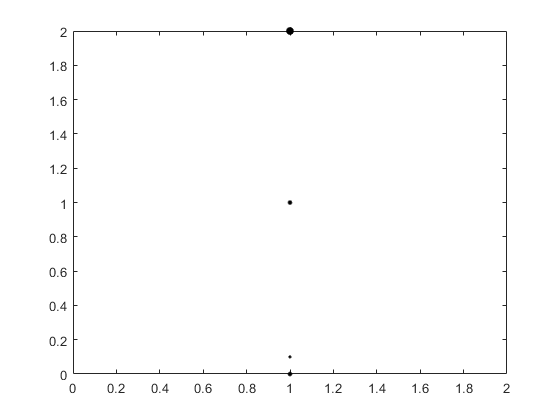

%suppose X=[0 -1;1 0]
X=[0 -1;1 0];
I=eye(2);

g=@(t) I+t*X;
v=[1 0]';
v1=g(1)*v;
v2=g(2)*v;
v3=g(.1)*v;

plot(v(1),v(2),'.','Color','k','MarkerSize',10)
hold on
plot(v1(1),v1(2),'.','Color','k','MarkerSize',10)
plot(v2(1),v2(2),'.','Color','k','MarkerSize',20)
plot(v3(1),v3(2),'.','Color','k','MarkerSize',5)
hold off

For a group of continuous transformation G, we can use the equation $G=e^{tX}$

and since $e^{tX}=\lim_{N \to \infty} (I+\frac{tX}{N})^N$, $X$ is called the generator of transformation (actually every multiple of $X$ could be taken as generator) and the transformation matrices on the either side of the equation does the same thing. An example is below.

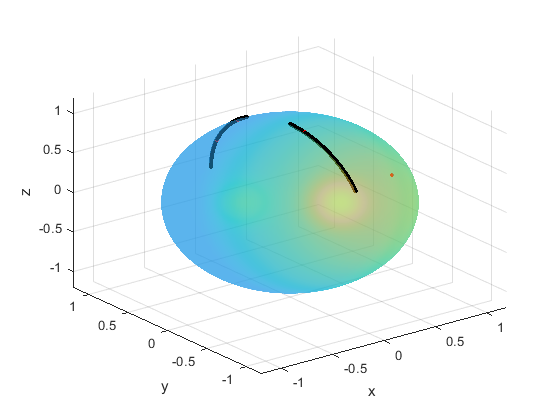




syms t

[x y z] = sphere(128);
h = surfl(x, y, z); 
set(h, 'FaceAlpha', 0.5)
shading interp
hold on

t=1;
N=10^(3);
I=eye(3);

%generators of So(3)
J1=[0  0   0;
    0  0 -1i;
    0 1i   0];

J2=[0  0 1i;
    0  0  0;
   -1i 0  0];

J3=[0  -1i 0;
    1i  0  0;
    0   0  0];

%generator (change the generator and see what it does)
X=J1;

v=[0 0 1;
   0 1 0;
   1 0 0]';

%infinite infinitesimal transformation
for ii=1:N
    R=(I-1i*t/N*X)^ii*v;
    plot3(R(1,:),R(2,:),R(3,:),'.','MarkerSize',10,'Color','k')
    hold on
end

%transformation when generator exponentiated
for tt=0:t/36:t
    v2=expm(-1i*tt*X)*v;
    plot3(v2(1,:),v2(2,:),v2(3,:),'.','MarkerSize',10,'Color','r')
end

xlabel('x')
ylabel('y')
zlabel('z')
axis([-1.2 1.2 -1.2 1.2 -1.2 1.2])
grid on
hold off


$$[J_i,J_j]=i \epsilon_{ijk}J_k$$


syms t



%Generators of SO(3)
%SO(3) acts on 3-vectors

J1SO3=[0  0   0;
       0  0  1i;
       0 -1i  0];

J2SO3=[0  0 -1i;
       0  0  0;
       1i 0  0];

J3SO3=[0  1i  0;
      -1i  0  0;
       0   0  0];


R1SO3=simplify(expm(1i*t*J1SO3))

$$R1SO3 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(t\right) & -\sin\left(t\right)\\ 0 & \sin\left(t\right) & \cos\left(t\right) \end{array}\right)$$

R2So3=simplify(expm(1i*t*J2SO3))

$$R2So3 = \left(\begin{array}{ccc} \cos\left(t\right) & 0 & \sin\left(t\right)\\ 0 & 1 & 0\\ -\sin\left(t\right) & 0 & \cos\left(t\right) \end{array}\right)$$

R3S03=simplify(expm(1i*t*J3SO3))

$$R3S03 = \left(\begin{array}{ccc} \cos\left(t\right) & -\sin\left(t\right) & 0\\ \sin\left(t\right) & \cos\left(t\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

res=commutator(J1SO3,J2SO3)

res =      0     1     0
    -1     0     0
     0     0     0



$$[\sigma_i,\sigma_j]=2i\epsilon_{ijk}\sigma_k$$



$$[J_i,J_j]=i \epsilon_{ijk}J_k$$


%Generators of SU(2) in 2X2
%SU(2) in 2X2 acts on quaternions with 0I+xi+yj+zk


$$R_i(\theta)=e^{i \theta J_i}$$



$$v=0I+xi+yj+zk$$



$$v'=R_i(\theta)vR_i(\theta)^{-1}$$




%Pauli matrices
s1=[0 1;
    1 0];

s2=[0 -1i;
    1i  0];

s3=[1 0;
    0 -1];

%generators
J1=sym(s1)/2

$$J1 = \left(\begin{array}{cc} 0 & \frac{1}{2}\\ \frac{1}{2} & 0 \end{array}\right)$$

J2=sym(s2)/2

$$J2 = \left(\begin{array}{cc} 0 & -\frac{1}{2}\,\mathrm{i}\\ \frac{1}{2}\,\mathrm{i} & 0 \end{array}\right)$$

J3=sym(s3)/2

$$J3 = \left(\begin{array}{cc} \frac{1}{2} & 0\\ 0 & -\frac{1}{2} \end{array}\right)$$


Rz=@(t) expm(1i*t*J3)

Rz = function_handle with value:
    @(t)expm(1i*t*J3)



v=q(0,1,0,0)

v =      0     1
    -1     0


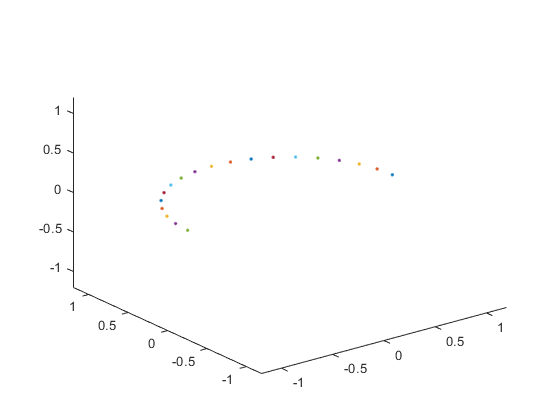

for tt=0:pi/18:pi
    v2=Rz(tt)*v*inv(Rz(tt));
    x=double((v2(1,2)-v2(2,1))/2);
    y=double((v2(1,2)+v2(2,1))/2i);
    z=double(v2(1,1)/1i);
    plot3(x,y,z,'.')
    hold on
end
axis([-1.2 1.2 -1.2 1.2 -1.2 1.2])
hold off


$$3.4.4 \ The \ Abstract \ Definition \ of \ a \ Lie \ Group$$



$$U(1) \cong SO(2) \cong S^1$$


$SU(2) \cong Sp(1) \cong S^3$       $Sp(1):$Compact symplectic group (the group of unit quaternions)

There is precisely one simply-connected Lie group corresponding to each Lie algebra.

We can think of SU(2) sphere actually has $4\pi$ radians instead of $2\pi$ while SO(3) sphere has $2\pi$ radians. So SU(2) has two copies of SO(3).

**3.6.1 The Finite-dimensional Irreducible Representations of SU(2)**

**Generators:**

$J_1, J_2, J_3$ where $J_3$ is diagonal. Simultaneously diagonalizable generators are called Cartan generators. In this case only $J_3$ is diagonal so it is the Cartan generator.

**Casimir Operator:**

$J^2=J_1^2+J_2^2+J_3^2$   where $[J^2,J_i]=0$ so that $J^2=\lambda I$(Schur's Lemma)

$J^2|b,m>=b|b,m>$        $b$ is the eigenvalue of Casimir operator while

$J_3|b,m>=m|b,m>$        m is the eigenvalue of Cartan generator

$J_+=J_1+iJ_2$           $J_-=J_1-iJ_2$        Ladder operators

$[J_3,J_{\pm}]=\pm J_\pm$        $[J_+,J_-]=2J_3$        Commutator relations

If we now investigate how these operators act on an eigenvector

$|b,m>$ of $J_3$ with eigenvalue $m$, we discover something remarkable:

$J_3(J_\pm|b,m>) = (\pm J_\pm + J_\pm J_3) |b,m>$   Using commutator relation

                      
$$=(m \pm 1)J_\pm |b,m>$$


Since $J_3|b,m\pm1>=(m\pm1)|b,m\pm1>$ we conclude that 


$$J_\pm|b,m> \equiv C|b,m\pm 1>$$
     

So the ladder operators $J\pm$ raise(lower) the eigenvalues of $J_3$ by 1. This process must come to an end, because eigenvectors with different eigenvalues are linearly independent and we are dealing with finite-dimensional representations.

So there is a maximum eigenvalue $j$ and

$J_+|b,j>=0$    and $J_-J_+|b,j>=0$

where 


$$J_-J_+=(J_1-iJ_2)(J_1+iJ_2)=J^2-J_3^2-J_3$$


so


$$J_-J_+|b,j>=J^2-J_3^2-J_3|b,j>=b-j^2-j|b,j>=0$$


Thus,


$$b-j^2-j=0    \longrightarrow b=j(j+1)$$


Similarly,

$J_+J_-|b,k>=(b-k^2+k)|b,k>=0$        where $k$ is the minimal eigenvalue and


$$b=-k(-k+1)=j(j+1) \longrightarrow k=-j$$


Since minimal eigenvalue is $-j$ while maximal one is $j$ and we can raise(lower)

the eigenvalues by 1 with ladder operators we conclude that there is $2j$ steps. Since

number of steps is an integer we conclude that


$$2j=integer \longrightarrow j=\frac{integer}{2}$$


So we have different representations for every value of $j$:


$$j=0 \ \ \ \ \ \ \ m=0 \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \  \ \ \ b=j(j+1)=0$$



$$j=1/2 \ \ \ \ \ m=1/2,-1/2 \ \ \ \ \  \ \ \ \ \ \ \ \ \ \ b=j(j+1)=\frac{3}{4}$$



$$j=1 \ \ \ \ \ \ \ m=1,0,-1 \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \  b=j(j+1)=2$$



$$j=3/2 \ \ \ \ \ m=3/2,1/2,-1/2,-3/2 \ \ \ \ \ b=j(j+1)=\frac{15}{4}$$


...

where $j$ is the maximum eigenvalue of $J_3$; $m$ are the eigenvalues of $J_3$ and

$b$ is the eigenvalues of the Casimir operator which are all the same.

We concluded that $J_\pm|b,m> \equiv C|b,m\pm1>$

After some calculation we find that


$$C=\sqrt{j(j+1)-m^2-m}$$


%Every finite dimensional representation of SU(2)
%the only variable is j, others follow it

%2j+1 gives the dimension e.g. for 2D j=1/2
j=sym(1);

%m is the eigenvalues of J3 and starts with the maximum eigenvalue
m=j:-1:-j

$$m = \left(\begin{array}{ccc} 1 & 0 & -1 \end{array}\right)$$

%J+ |b,m> = Cp |b,m+1> 
Cp=sqrt(j*(j+1)-m.^2-m)

$$Cp = \left(\begin{array}{ccc} 0 & \sqrt{2} & \sqrt{2} \end{array}\right)$$

%J- |b,m> = Cm |b,m-1> 
Cm=sqrt(j*(j+1)-m.^2+m)

$$Cm = \left(\begin{array}{ccc} \sqrt{2} & \sqrt{2} & 0 \end{array}\right)$$

%representation label
b=j*(j+1)

$$b = 2$$

%J3 is diagonal and the values are m
J3=diag(m)

$$J3 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & -1 \end{array}\right)$$

%eigenvectors of J3
evec=eye(length(J3))

evec =      1     0     0
     0     1     0
     0     0     1


%this is a little tricky, J+ moves the columns of evec to the right
% and multiply each colum with Cp

el=length(evec);

%evec(:,[el 1:(el-1)]) gives evec with permuted to right
Jp=(evec(:,[el 1:(el-1)])*diag(Cp))*inv(evec)

$$Jp = \left(\begin{array}{ccc} 0 & \sqrt{2} & 0\\ 0 & 0 & \sqrt{2}\\ 0 & 0 & 0 \end{array}\right)$$

%evec(:,[2:el 1]) gives evec with permuted to left
Jm=(evec(:,[2:el 1])*diag(Cm))*inv(evec)

$$Jm = \left(\begin{array}{ccc} 0 & 0 & 0\\ \sqrt{2} & 0 & 0\\ 0 & \sqrt{2} & 0 \end{array}\right)$$

%J1=1/2(J+ + J-) by definition
J1=1/2*(Jp+Jm)

$$J1 = \left(\begin{array}{ccc} 0 & \frac{\sqrt{2}}{2} & 0\\ \frac{\sqrt{2}}{2} & 0 & \frac{\sqrt{2}}{2}\\ 0 & \frac{\sqrt{2}}{2} & 0 \end{array}\right)$$

%J1=1/2(J- - J+) by definition
J2=1i/2*(Jm-Jp)

$$J2 = \left(\begin{array}{ccc} 0 & -\frac{\sqrt{2}\,\mathrm{i}}{2} & 0\\ \frac{\sqrt{2}\,\mathrm{i}}{2} & 0 & -\frac{\sqrt{2}\,\mathrm{i}}{2}\\ 0 & \frac{\sqrt{2}\,\mathrm{i}}{2} & 0 \end{array}\right)$$

J3

$$J3 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & -1 \end{array}\right)$$

isequal(commutator(J1,J2),1i*J3)

ans = logical
   1



% exponentiating generators we get actual group members
syms t
g1=simplify(expm(-1i*t*J1),'Steps',100)

$$g1 = \begin{array}{l} \left(\begin{array}{ccc} \frac{\cos\left(t\right)}{2}+\frac{1}{2} & \sigma_{1} & \frac{\cos\left(t\right)}{2}-\frac{1}{2}\\ \sigma_{1} & \cos\left(t\right) & \sigma_{1}\\ \frac{\cos\left(t\right)}{2}-\frac{1}{2} & \sigma_{1} & \frac{\cos\left(t\right)}{2}+\frac{1}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\sqrt{2}\,\sin\left(t\right)\,\mathrm{i}}{2} \end{array}$$

g2=simplify(expm(-1i*t*J2),'Steps',100)

$$g2 = \left(\begin{array}{ccc} \frac{\cos\left(t\right)}{2}+\frac{1}{2} & -\frac{\sqrt{2}\,\sin\left(t\right)}{2} & \frac{1}{2}-\frac{\cos\left(t\right)}{2}\\ \frac{\sqrt{2}\,\sin\left(t\right)}{2} & \cos\left(t\right) & -\frac{\sqrt{2}\,\sin\left(t\right)}{2}\\ \frac{1}{2}-\frac{\cos\left(t\right)}{2} & \frac{\sqrt{2}\,\sin\left(t\right)}{2} & \frac{\cos\left(t\right)}{2}+\frac{1}{2} \end{array}\right)$$

g3=simplify(expm(-1i*t*J3),'Steps',1000)

$$g3 = \left(\begin{array}{ccc} {\mathrm{e}}^{-t\,\mathrm{i}} & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & \cos\left(t\right)+\sin\left(t\right)\,\mathrm{i} \end{array}\right)$$

Functions

function res=commutator(X,Y)
    res=X*Y-Y*X;
end